% Find Nearest Points in Clustered Data using rangesearch
% https://ww2.mathworks.cn/help/stats/rangesearch.html

## Generate 5000 random points from each of three distinct multivariate normal distributions.

Shift the means of the distributions so that the randomly generated points are likely to form three separate clusters.

rng('default')  % For reproducibility
N = 5;
dist = 10;
%  mvnrnd - Multivariate normal random numbers
%     This MATLAB function returns a matrix R of n random vectors chosen from
%     the same multivariate normal distribution, with mean vector mu and
%     covariance matrix Sigma.
%     R = mvnrnd(mu,Sigma,n)
%     R = mvnrnd(mu,Sigma)
X = [mvnrnd([0 0],eye(2),N);
     mvnrnd(dist*[1 1],eye(2),N);
     mvnrnd(dist*[-1 -1],eye(2),N)];

## For each point in X, find the points in X that are within a radius dist away from the point.

For faster computation, specify to keep the indices of the nearest neighbors unsorted. Select the first point in X, and find its nearest neighbors.

Idx = rangesearch(X,X,dist,'SortIndices',false);
x = X(1,:);
nearestPoints = X(Idx{1},:);

## Find the values in X that are not the nearest neighbors of x.

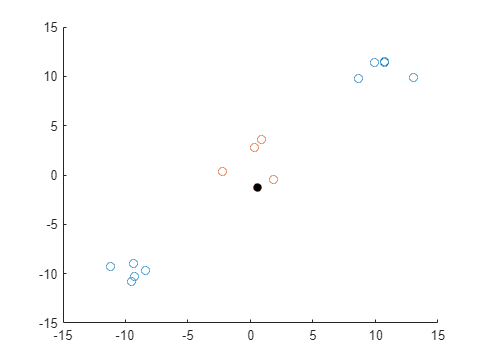

nonNearestIdx = true(size(X,1),1);
nonNearestIdx(Idx{1}) = false;

% Display those points in one color and the nearest neighbors of x in a different color. 
scatter(X(nonNearestIdx,1),X(nonNearestIdx,2))
hold on
scatter(nearestPoints(:,1),nearestPoints(:,2))

scatter(x(1),x(2),'black','filled')  % Label the point x with a black, filled circle.
hold off